clear all;clc;
Noise = imread('Fig0507(b)(ckt-board-gauss-var-400).tif');
imshow(Noise);title('高斯噪声');

[m,n] = size(Noise);
AMF = double(Noise); 	% 算术均值
GMF = double(Noise);	% 几何均值
D = 5;
d = (D-1)/2;
NoisePad=padarray(Noise,[d,d],'symmetric');
for i=1:m
    for j=1:n
        tmp = NoisePad(i:i+2*d,j:j+2*d);
        AMF(i,j) = sum(tmp(:))/D^2;
        GMF(i,j) = prod(tmp(:))^(1/D^2);
    end
end
subplot(1,2,1);imshow(mat2gray(AMF));title('算术均值  5*5');
subplot(1,2,2);imshow(mat2gray(GMF));title('几何均值  5*5');

clear all;clc;
NoisePepper = imread('Fig0508(a)(circuit-board-pepper-prob-pt1).tif');
NoiseSalt = imread('Fig0508(b)(circuit-board-salt-prob-pt1).tif');
subplot(1,2,1);imshow(NoisePepper);title('椒噪声');
subplot(1,2,2);imshow(NoiseSalt);title('盐噪声');

NoisePepper = double(NoisePepper);
NoiseSalt = double(NoiseSalt);
NoisePepperPad=padarray(NoisePepper,[1,1],'symmetric');
NoiseSaltPad=padarray(NoiseSalt,[1,1],'symmetric');

[m,n] = size(NoisePepper);
CHMFPepper1 = NoisePepper;
CHMFPepper2 = NoisePepper;
CHMFPepper3 = NoisePepper;
CHMFPepper4 = NoisePepper;
CHMFSalt1 = NoiseSalt;
CHMFSalt2 = NoiseSalt;
CHMFSalt3 = NoiseSalt;
CHMFSalt4 = NoiseSalt;
Q1 = 1; Q2 = 5; d=1;
% 逆谐波均值
for i=1:m
    for j=1:n
        tmp_a = NoisePepperPad(i:i+2*d,j:j+2*d);
        tmp_b = NoiseSaltPad(i:i+2*d,j:j+2*d);
        CHMFPepper1(i,j) = sum(tmp_a(:).^(Q1+1))/sum(tmp_a(:).^Q1);
        CHMFSalt1(i,j) = sum(tmp_b(:).^(Q1+1))/sum(tmp_b(:).^Q1);
        CHMFPepper2(i,j) = sum(tmp_a(:).^(1-Q1))/sum(tmp_a(:).^(-Q1));
        CHMFSalt2(i,j) = sum(tmp_b(:).^(1-Q1))/sum(tmp_b(:).^(-Q1));
        CHMFPepper3(i,j) = sum(tmp_a(:).^(Q2+1))/sum(tmp_a(:).^Q2);
        CHMFSalt3(i,j) = sum(tmp_b(:).^(Q2+1))/sum(tmp_b(:).^Q2);
        CHMFPepper4(i,j) = sum(tmp_a(:).^(1-Q2))/sum(tmp_a(:).^(-Q2));
        CHMFSalt4(i,j) = sum(tmp_b(:).^(1-Q2))/sum(tmp_b(:).^(-Q2));
    end
end
subplot(2,4,1),imshow(uint8(CHMFPepper1)),title('Q=1 椒');
subplot(2,4,2),imshow(uint8(CHMFPepper2)),title('Q=-1 椒');
subplot(2,4,3),imshow(uint8(CHMFPepper3)),title('Q=5 椒');
subplot(2,4,4),imshow(uint8(CHMFPepper4)),title('Q=-5 椒');

subplot(2,4,5),imshow(uint8(CHMFSalt1)),title('Q=1 盐');
subplot(2,4,6),imshow(uint8(CHMFSalt2)),title('Q=-1 盐');
subplot(2,4,7),imshow(uint8(CHMFSalt3)),title('Q=5 盐');
subplot(2,4,8),imshow(uint8(CHMFSalt4)),title('Q=-5 盐');


clear all;clc;
Noise = imread('Fig0512(b)(ckt-uniform-plus-saltpepr-prob-pt1).tif');
imshow(Noise);title('原图像');

[m,n] = size(Noise);
AMF = double(Noise);  % 算术均值
GMF = double(Noise);  % 几何均值
MedF = double(Noise);  % 中值
ATMF = double(Noise);  % alpha修正均值

D = 3;  % 检测窗口大小
d = (D-1)/2;
t = 2;  % alpha修正均值中的参数d
NoisePad=padarray(Noise,[d,d],'symmetric');

for i=1:m
    for j=1:n
        tmp = NoisePad(i:i+2*d,j:j+2*d);
        sort_tmp = sort(tmp(:));
        alpha = sort_tmp(t+1:D^2-t);
        AMF(i,j) = sum(tmp(:))/D^2;
        GMF(i,j) = prod(tmp(:))^(1/D^2);
        MedF(i,j) = sort_tmp((D^2-1)/2);
        ATMF(i,j) = sum(alpha(:))/(D^2-2*t);
    end
end

subplot(2,2,1),imshow(mat2gray(AMF)),title('算术均值');
subplot(2,2,2),imshow(mat2gray(GMF)),title('几何均值');
subplot(2,2,3),imshow(mat2gray(MedF)),title('中值');
subplot(2,2,4),imshow(mat2gray(ATMF)),title('alpha修正均值'); 


clear all;clc;
Noise = imread('Fig0514(a)(ckt_saltpep_prob_pt25).tif');
imshow(Noise);title('原图像');

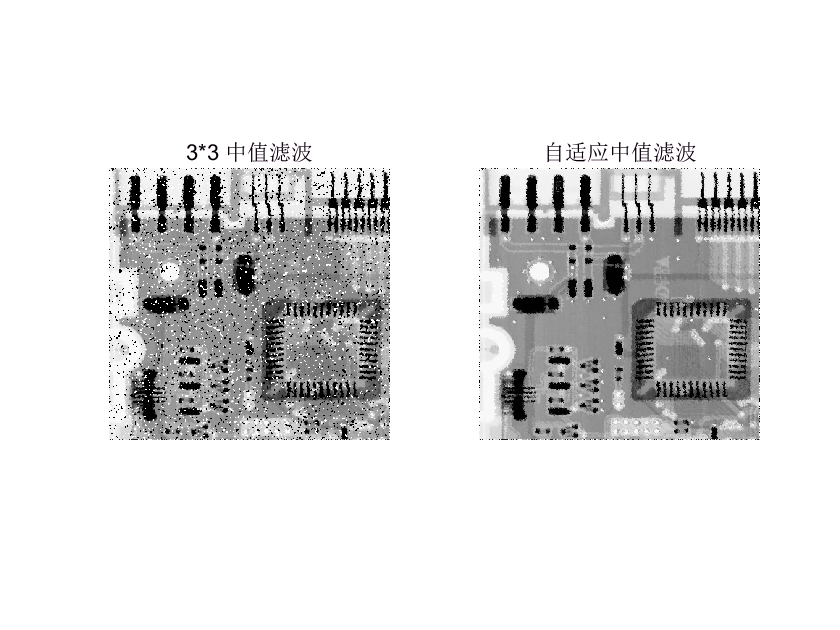

[m,n] = size(Noise);
Med3 = double(Noise);  % 中值
AdpMed = double(Noise);  % 自适应中值

NoisePad=padarray(Noise,[1,1],'symmetric');

for i=1:m
    for j=1:n
        d = 1;
        while(true)
            D = 2 * d + 1;
            if i-d<=0 || i+d>m || j-d<=0 || j+d>n
                AdpMed(i,j)=Noise(i,j);
                break;
            end
            tmp=NoisePad(i-d:i+d,j-d:j+d);
            sort_tmp = sort(tmp(:));
            Zmin = sort_tmp(1);
            Zmax = sort_tmp(D^2);
            Zmed = sort_tmp((D^2+1)/2);
            if d == 1
                Med3(i,j)=Zmed;
            end
            if Zmed>Zmin && Zmed<Zmax
                if Noise(i,j)>Zmin && Noise(i,j)<Zmax
                    AdpMed(i,j) = Noise(i,j);
                    break;
                else
                    AdpMed(i,j) = Zmed;
                    break;
                end
            else
                d=d+1;
            end
        end
    end
end

subplot(1,2,1),imshow(uint8(Med3)),title('3*3 中值滤波');
subplot(1,2,2),imshow(uint8(AdpMed)),title('自适应中值滤波');